# Zadanie 2.2

# Najpierw rozwiązujemy zadanie 2.1 

## Zagadnienia cieplno-przepływowe reaktorów jądrowych, Cwiczenia 2, 20-12-2024, Rewizja 2

clear; close all; clc;

## Dane - część danych z zadania 1.1

q_th = 4600e6		% [W] moc cieplna rdzenia

q_th =       4.6e+09


W = 75643000/3600 	% [kg/s] przepływ chlodziwa przez rdzen

W =         21012


p = 155		        % [bar]	ciśnienie	

p =    155


Tin = 295.6		    % [degC] temperatura wlotowa		  			

Tin =         295.6



N_FA = 241          % ilość kaset paliwowych, FA - Fuel Assemblies [-]

N_FA =    241


N_rod = 265         % ilość prętów w kasecie [-]

N_rod =    265


H = 4200/1000       % wysokość aktywnej częsci rdzenia (kaset paliwowych/prętów paliwowych) [m]

H =           4.2


skok = 214/1000     % skok siatki kaset paliwowych - odległość między środkami kaset [m]

skok =         0.214



d_ex = 5/100;       % [m] Długość ekstrapolacji
Pxy = 1.438;        % [-] ????????? Wsp. promieniowy nierównomierności rozkładu - odczytany z mapy rdzenia

## 1) Średni przyrost temperatury w całym rdzeniu i średnim kanale

cp = 1000*XSteam('Cp_pT', p,Tin) % [kJ/kg/K] cieplo wlasciwe dla T wlotowej

cp =        5356.6


deltaT = q_th / (cp*W) 

deltaT =        40.869


Tout = Tin + deltaT

Tout =        336.47


Tavg = (Tin+Tout)/2

Tavg =        316.03



% w średnim kanale będzie identyczny przyrost

## Dodatkowy materiał - demonstracja procesu iteracyjnego

można iteracyjnie poprawić wynik dla 1 iteracji iteracja 1

% iteracja 1
disp('Iteracja 1')

Iteracja 1


cp1 = 1000*XSteam('Cp_pT', p,Tavg) % [kJ/kg/K] cieplo wlasciwe dla T wlotowej

cp1 =        5967.2


deltaT1 = q_th / (cp1*W) 

deltaT1 =        36.688


Tout1 = Tin + deltaT1

Tout1 =        332.29



% iteracja 2
disp('Iteracja 2')

Iteracja 2


Tavg2 = (Tin + Tout1)/2

Tavg2 =        313.94


cp2 = 1000*XSteam('Cp_pT', p,Tavg2) % [kJ/kg/K] cieplo wlasciwe dla T wlotowej

cp2 =        5884.2


deltaT2 = q_th / (cp2*W) 

deltaT2 =        37.205


Tout2 = Tin + deltaT2

Tout2 =        332.81


## 2) Przyrost temperatury w rdzeniu w najgorętszym kanale

Przyrost temperatury w rdzeniu w najgorętszym kanale zakładając średni przepływ 

deltaT_max = deltaT*Pxy             % [K] przyrost temperatury

deltaT_max =         58.77


Tout_max = Tin + deltaT_max         % [K] temperatura na wylocie

Tout_max =        354.37


Tavg_max = (Tin + Tout_max)/2       % [K] srednia temperatura

Tavg_max =        324.99



disp('Iteracja 1')

Iteracja 1


cp_max1 = 1000*XSteam('Cp_pT', p,Tavg_max) % [kJ/kg/K] cieplo wlasciwe dla T wlotowej

cp_max1 =        6413.6


deltaT1_max = Pxy*q_th / (cp_max1*W) 

deltaT1_max =        49.085


% q_th/W  jest takie samo dla kanału jak i dla całego rdzenia - w tym
% przypadku i przy tych założeniach
Tout_max1 = Tin + deltaT1_max

Tout_max1 =        344.68


% mozna wiecej ale dla prostoty jedna iteracja

## 3) Dla kanału średniego i najgorętszego oblicz i wykreśl rozkład temperatury/entalpi wzdłuż kanału oraz rozkład mocy liniowej

He = H + 2*d_ex                 % [m] wysokość rdzenia z dodanymi 2x długościami ekstrpolacji

He =           4.3


W_kanal = W / (N_FA*N_rod)		% [kg/s] przepływ przez pojedyńczy kanał

W_kanal =       0.32901


q_kanal = q_th / (N_FA*N_rod)   % [W] moc sredniego kanalu - srednia moc kanalu

q_kanal =         72027


q_prim_kanal = q_kanal / H		% [W/m] srednia moc liniowa

q_prim_kanal =         17149


Wyliczenia liniowej mocy  maksylamej dla rozkladu kosinusoidalnego.

Osiowy rozkład mocy jest typu ścięty kosinus. Długość ekstrapolacji załóż 5 cm.

Maksymalną moc liniowa zadana równaniem - teoretyczna wartość dla rozkładu ścięty kosinus

q0_prim = pi*q_kanal/(He*2*sin((pi*H)/(2*He)))      % [W/m] maksymalna moc dla średniego kanału

q0_prim =         26329


q0_prim_max = q0_prim * Pxy                         % [W/m] maksymalna moc dla kanału gorącego

q0_prim_max =         37861


Rozkład mocy liniowej w kanale srednim i max

z = linspace(-H/2,H/2,100)  % przestrzeń punktów wzdłuż kanału, 100 podziałów, rozpięta od dna rdzenia do szytu

z =          -2.1      -2.0576      -2.0152      -1.9727      -1.9303      -1.8879      -1.8455       -1.803      -1.7606      -1.7182      -1.6758      -1.6333      -1.5909      -1.5485      -1.5061      -1.4636      -1.4212      -1.3788      -1.3364      -1.2939      -1.2515      -1.2091      -1.1667      -1.1242      -1.0818      -1.0394     -0.99697     -0.95455     -0.91212      -0.8697     -0.82727     -0.78485     -0.74242         -0.7     -0.65758     -0.61515     -0.57273      -0.5303     -0.48788     -0.44545     -0.40303     -0.36061     -0.31818     -0.27576     -0.23333     -0.19091     -0.14848     -0.10606    -0.063636    -0.021212



q_prim =  q0_prim * cos(pi*z/He)                  % Rozkład mocy liniowej w kanale średnim

q_prim =        961.59       1776.5       2589.8       3400.5         4208       5011.4       5810.1       6603.1       7389.8       8169.4       8941.2       9704.3        10458        11202        11935        12657        13366        14063        14746        15414        16069        16707        17330        17936        18525        19095        19648        20182        20696        21191        21665        22118        22550        22960        23349        23714        24058        24378        24674        24947        25196        25421        25621        25797        25947        26073        26174        26250        26301        26326


q_prim_max =  q0_prim_max * cos(pi*z/He)          % Rozkład mocy liniowej w kanale gorącym

q_prim_max =        1382.8       2554.7       3724.1       4889.9       6051.1       7206.4       8354.9       9495.3        10627        11748        12857        13955        15039        16108        17163        18200        19220        20222        21204        22166        23107        24025        24920        25792        26638        27459        28254        29021        29761        30472        31154        31806        32427        33017        33575        34101        34595        35055        35481        35874        36232        36555        36843        37095        37312        37494        37639        37748        37820        37857


Wykresy

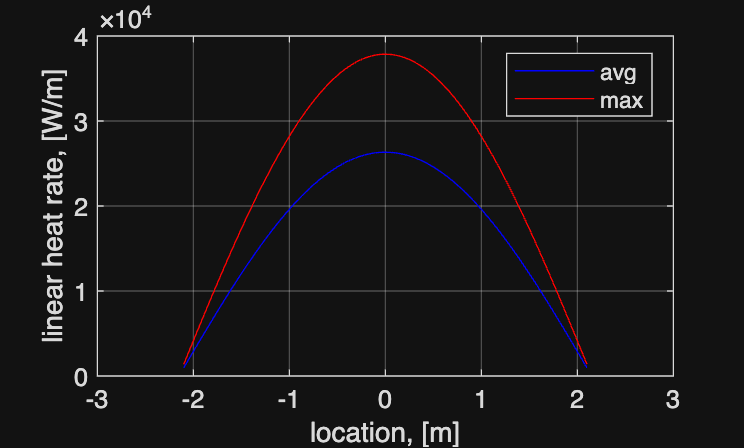

figure(1); grid on; box on; hold on;

xlabel('location, [m]')
ylabel('linear heat rate, [W/m]')
plot(z, q_prim, '-b')
plot(z, q_prim_max, '-r')
legend('avg','max')

Rozkład temperatury w kanale srednim i gorącym

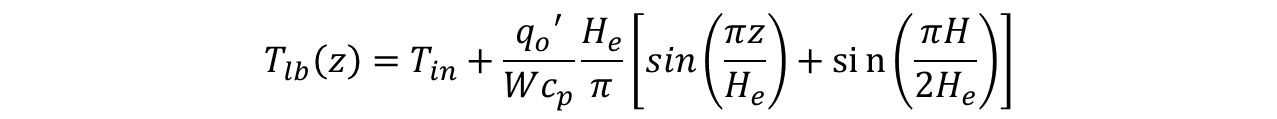

T_lb = Tin + (q0_prim/(W_kanal*cp))*(He/pi)*(sin(pi * z / He) + sin(pi * H / (2 * He)));
T_lb_max = Tin + (q0_prim_max/(W_kanal*cp))*(He/pi)*(sin(pi * z / He) + sin(pi * H / (2 * He)));

Wykres

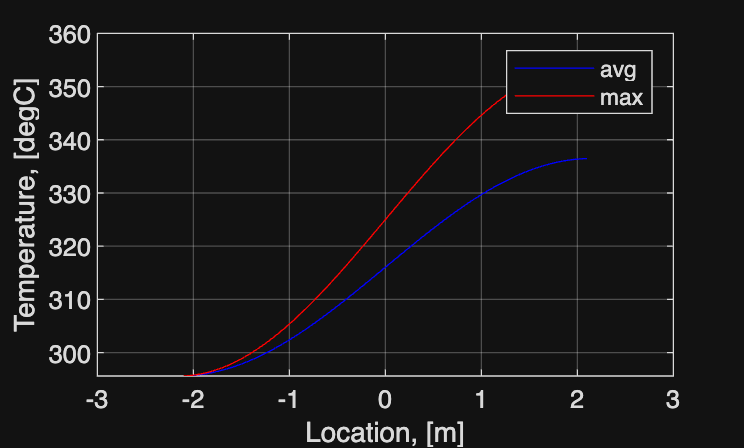

figure(2); grid on; box; hold on;
plot(z, T_lb, '-b')
plot(z, T_lb_max, '-r')
legend('avg','max')
xlabel('Location, [m]')
ylabel('Temperature, [degC]')

# Zadanie 2.2 

## 1) Wyznacz rozkłady temperatury i strumienia ciepła na powierzchni najgorętszego i średniego pręta paliwowego

Zaczynamy od określenia wymiany ciepła między przypływem, a koszulką elementu paliwowego

Dane:

d = 9.5/1000 % średnica pręta paliwowego

d =        0.0095


pitch = 112.6/1000 % skok siatki prętów paliwowych

pitch =        0.1126


Średnica hydrauliczna:

Asqr = pitch^2 - (pi/4)*d^2 % pole przepływu

Asqr =      0.012608


Pw = pi*d % obwód mokry

Pw =      0.029845


Dh = 4*Asqr/Pw % średnica hydrauliczna

Dh =        1.6898


Liczba Reynoldsa oraz Prandtla

G = W_kanal/Asqr % strumień masy

G =        26.095


mu = XSteam('my_pT', p, Tin) % lepkość dynamiczna

mu =     9.023e-05


Re = G*Dh/mu % liczba Reynoldsa

Re =    4.8869e+05


cp = 1000*XSteam('Cp_pT', p, Tin)

cp =        5356.6


k = XSteam('tc_pt', p, Tin)

k =       0.56759


Pr = cp * mu / k % liczba Prandtla

Pr =       0.85156


Liczba Nusselta - korelacja Dittusa-Boltera 

Nu_DB = 0.023*(Re^(0.8))*Pr^(0.4) % liczba Nusselta - DB

Nu_DB =        767.44


Liczba Nusselta - korelacja Markoczego

B = (4/pi)*(pitch/d)^2 - 1

B =        177.87


Nu_Markoczy = (1 + 0.91*(Re^(-0.1))*(Pr^0.4)*(1 - 2*exp(-B)))*Nu_DB

Nu_Markoczy =        944.15


Współczynnik przejmowania ciepła

h_DB = Nu_DB*k/Dh

h_DB =        257.78


h_Markoczy = Nu_Markoczy*k/Dh

h_Markoczy =        317.13


h = h_Markoczy

h =        317.13


Przyrost temperatury między przepływem, a powierzchnią paliwa dla średniego i gorącego kanału

deltaT_wall = q_prim./(pi*d*h)

deltaT_wall =         101.6        187.7       273.62       359.28       444.59       529.47       613.85       697.64       780.76       863.12       944.66       1025.3       1104.9       1183.5         1261       1337.2       1412.2       1485.8       1557.9       1628.6       1697.7       1765.2         1831         1895       1957.2       2017.5       2075.9       2132.3       2186.6       2238.8       2288.9       2336.8       2382.5       2425.8       2466.9       2505.5       2541.8       2575.6       2606.9       2635.7         2662       2685.8       2706.9       2725.5       2741.4       2754.7       2765.4       2773.4       2778.7       2781.4


deltaT_wall_max = q_prim_max/(pi*d*h)

deltaT_wall_max =        146.09       269.91       393.46       516.64       639.32       761.38       882.72       1003.2       1122.7       1241.2       1358.4       1474.4       1588.9       1701.9       1813.3       1922.9       2030.7       2136.5       2240.3       2341.9       2441.3       2538.3       2632.9         2725       2814.4       2901.2       2985.1       3066.2       3144.3       3219.5       3291.5       3360.4         3426       3488.3       3547.3       3602.9       3655.1       3703.7       3748.7       3790.2         3828       3862.1       3892.6       3919.3       3942.2       3961.3       3976.6       3988.2       3995.8       3999.7


Temperatura powierchni koszulki elementu paliwowego

T_co = T_lb + deltaT_wall

T_co =         397.2       483.33        569.3       655.03       740.44       825.43       909.94       993.88       1077.2       1159.7       1241.5       1322.3       1402.2       1481.1       1558.8       1635.3       1710.6       1784.5         1857         1928       1997.5       2065.4       2131.6         2196       2258.7       2319.5       2378.3       2435.2         2490       2542.7       2593.3       2641.8         2688       2731.9       2773.4       2812.7       2849.5       2883.9       2915.8       2945.2       2972.1       2996.5       3018.3       3037.4         3054       3067.9       3079.2       3087.9       3093.8       3097.1


T_co_max = T_lb + deltaT_wall_max

T_co_max =        441.69       565.54       689.15        812.4       935.17       1057.3       1178.8       1299.4       1419.1       1537.8       1655.2       1771.4       1886.2       1999.4       2111.1         2221       2329.1       2435.3       2539.4       2641.4       2741.1       2838.5       2933.6         3026       3115.9       3203.1       3287.5       3369.1       3447.7       3523.4       3595.9       3665.3       3731.5       3794.4       3853.9       3910.1       3962.8         4012       4057.6       4099.7       4138.1       4172.8       4203.9       4231.2       4254.7       4274.5       4290.5       4302.6       4310.9       4315.4


Wykresy

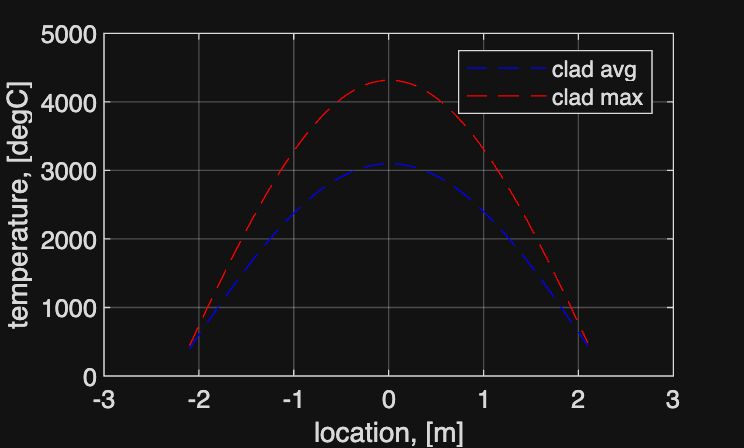

figure(3); grid on; box; hold on; % nowy wykres
%figure(2) % nałóż na wykres temperatury przepływu
hold on;
plot(z, T_co, '--b')
plot(z, T_co_max, '--r')
%legend('flow avg','flow max','clad avg','clad max')
legend('clad avg','clad max')
xlabel('location, [m]')
ylabel('temperature, [degC]')


%legend(["flow avg", "flow max", "clad avg", "clad max"], "Position", [0.13 0.74 0.1780, 0.1823])

Obliczenia strumieni ciepła

q_bis =  q0_prim * cos(pi*z/He)/(pi*d)                  % Rozkład mocy liniowej w kanale średnim

q_bis =         32219        59525        86774   1.1394e+05   1.4099e+05   1.6791e+05   1.9467e+05   2.2125e+05    2.476e+05   2.7373e+05   2.9958e+05   3.2516e+05   3.5041e+05   3.7534e+05    3.999e+05   4.2407e+05   4.4784e+05   4.7118e+05   4.9407e+05   5.1648e+05    5.384e+05    5.598e+05   5.8066e+05   6.0096e+05   6.2069e+05   6.3982e+05   6.5833e+05   6.7622e+05   6.9345e+05   7.1002e+05    7.259e+05   7.4109e+05   7.5556e+05   7.6931e+05   7.8233e+05   7.9458e+05   8.0608e+05    8.168e+05   8.2674e+05   8.3588e+05   8.4422e+05   8.5175e+05   8.5846e+05   8.6435e+05    8.694e+05   8.7362e+05   8.7701e+05   8.7954e+05   8.8124e+05   8.8209e+05


q_bis_max =  q0_prim_max * cos(pi*z/He)/(pi*d)          % Rozkłąd mocy liniowej w kanale gorącym

q_bis_max =         46332        85597   1.2478e+05   1.6384e+05   2.0275e+05   2.4146e+05   2.7994e+05   3.1815e+05   3.5606e+05   3.9362e+05    4.308e+05   4.6757e+05    5.039e+05   5.3973e+05   5.7505e+05   6.0982e+05     6.44e+05   6.7756e+05   7.1047e+05    7.427e+05   7.7422e+05   8.0499e+05   8.3499e+05   8.6418e+05   8.9255e+05   9.2006e+05   9.4668e+05    9.724e+05   9.9718e+05    1.021e+06   1.0438e+06   1.0657e+06   1.0865e+06   1.1063e+06    1.125e+06   1.1426e+06   1.1591e+06   1.1746e+06   1.1889e+06    1.202e+06    1.214e+06   1.2248e+06   1.2345e+06   1.2429e+06   1.2502e+06   1.2563e+06   1.2611e+06   1.2648e+06   1.2672e+06   1.2684e+06


Wykres

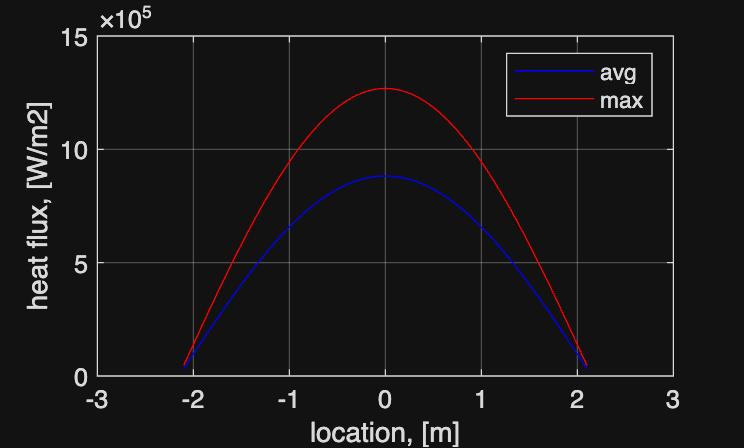

figure(4); grid on; box; hold on;
plot(z, q_bis, '-b')
plot(z, q_bis_max, '-r')
legend('avg','max')
xlabel('location, [m]')
ylabel('heat flux, [W/m2]')

## 2) Oszacuj lokalizację i maksymalną temperaturę i strumień ciepła na zewnętrznej powierzchni koszulki najgorętszego pręta paliwowego

Określ maksymalną temperaturę

max(T_co)

ans =        3097.8


[~, indeks1] = max(T_co)

indeks1 =     51


z(indeks1)

ans =      0.021212


max(T_co_max)

ans =          4316


[~, indeks2] = max(T_co_max)

indeks2 =     51


z(indeks2)

ans =      0.021212


Określ lokalizację maksymalnej temperatury

Określ maksymalny strumień ciepła wraz z lokalizacją

max(q_bis)

ans =    8.8209e+05


[~, indeks1] = max(q_bis)

indeks1 =     50


z(indeks1)

ans =     -0.021212


max(q_bis_max)

ans =    1.2684e+06


[~, indeks2] = max(q_bis_max)

indeks2 =     50


z(indeks2)

ans =     -0.021212


Określ lokalizację